# **Computer Vision**

**Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

**Student(s):**

**Date:**

# Topic 2. Geometric corrections 

To correct the effect of geometric transformations we must calculate the matrix that allows us to change the position of the input pixels and place them in the correct/undistorted output positions. In Matlab, the function we use for this is es [`tform = estgeotform2d(matchedPoints1,matchedPoints2,transformType)`](https://www.mathworks.com/help/releases/R2023a/vision/ref/estgeotform2d.html?browser=F1help#d124e211773?browser=F1help)`,` which estimates the matrix necessary to match the `matchedPoints1` of the input image with the `matchedPoints2` of the output image. In this exercise, we will provide you as a variable the values of matchedPoints2 where the pixels of the output image should be located after the transformation.

# Rotation correction

To calculate the matrix necessary to correct a rotated image (with or without scaling) we only need 2 points. In this case we will select the two furthest points  from the rings of Saturn and the code is prepared to rotate them and place them horizontally.

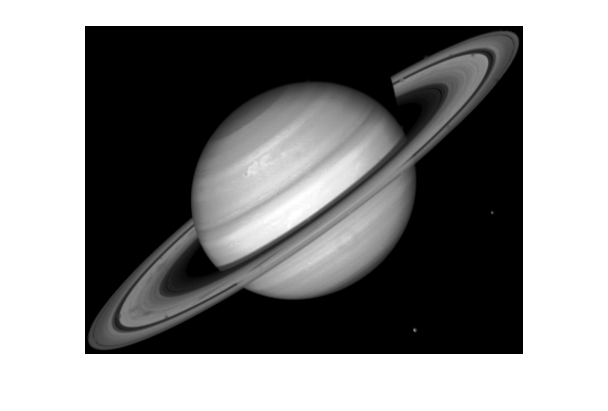

Error using getpts
Interruption during mouse point selection.

Error in impixel>parse_inputs (line 199)
        [xi,yi] = getpts(ancestor(h,'axes'));

Error in impixel (line 76)
[a,cm,xi,yi,x,y] = parse_inputs(varargin{:});

clc
clear all;
close all;

% Read original image.
I = imread('saturn.tif');
% NOTE: impixel 
% Use normal button clicks to select pixels. 
% Press Backspace or Delete to remove the previously selected pixel. 
% To add a final pixel and finish pixel selection in one step, press shift-click, or right-click or double-click. 
% To finish selecting pixels without adding a final pixel, press Return.
figure
[x, y, P] = impixel(I);

% Define the destination points to create a 45-degree rotation
dstPoints = [150 50; ...
            100 200]; % Adjust the values as per your desired orientation

% Estimate the geometric transformation matrix
[tform, inlierIndex, status] = estgeotform2d(srcPoints, dstPoints, 'similarity');

% Apply the transformation to the input image
destino = imwarp(I, tform);

% Display the transformed image
figure; imshow(destino);


Modify the values of the destination points so that the final image is in a different orientation and display it.

dstPoints = [];


# Perspective Correction with Homography

To correct the perspective of an object it is necessary to estimate the perspective transformation. Four pairs of corresponding points are sufficient to recover a perspective transformation between two images. The objective of this practice is to correct the perspective of the card in the image "**card.jpg**",

It is requested: 

- Read the image "**card.jpg**". Click on the four corners of the card to get the first four points using the **impixel** function. Note: Use the following order to obtain the four points: 1) Top left corner, 2) Top right corner, 3) Bottom right corner, 4) Bottom left corner.

- Calculate the four points of the poker card without perspective distortion, taking into account that a poker card has a size of approximately 100 mm by 150 mm..

- Estimate the perspective transformation using the **estgeotform2d** function knowing that in this case the transformation type is "**projective**"`.` 

- Apply the perspective transformation using the **imwarp** function.

- Show the undistorted card.

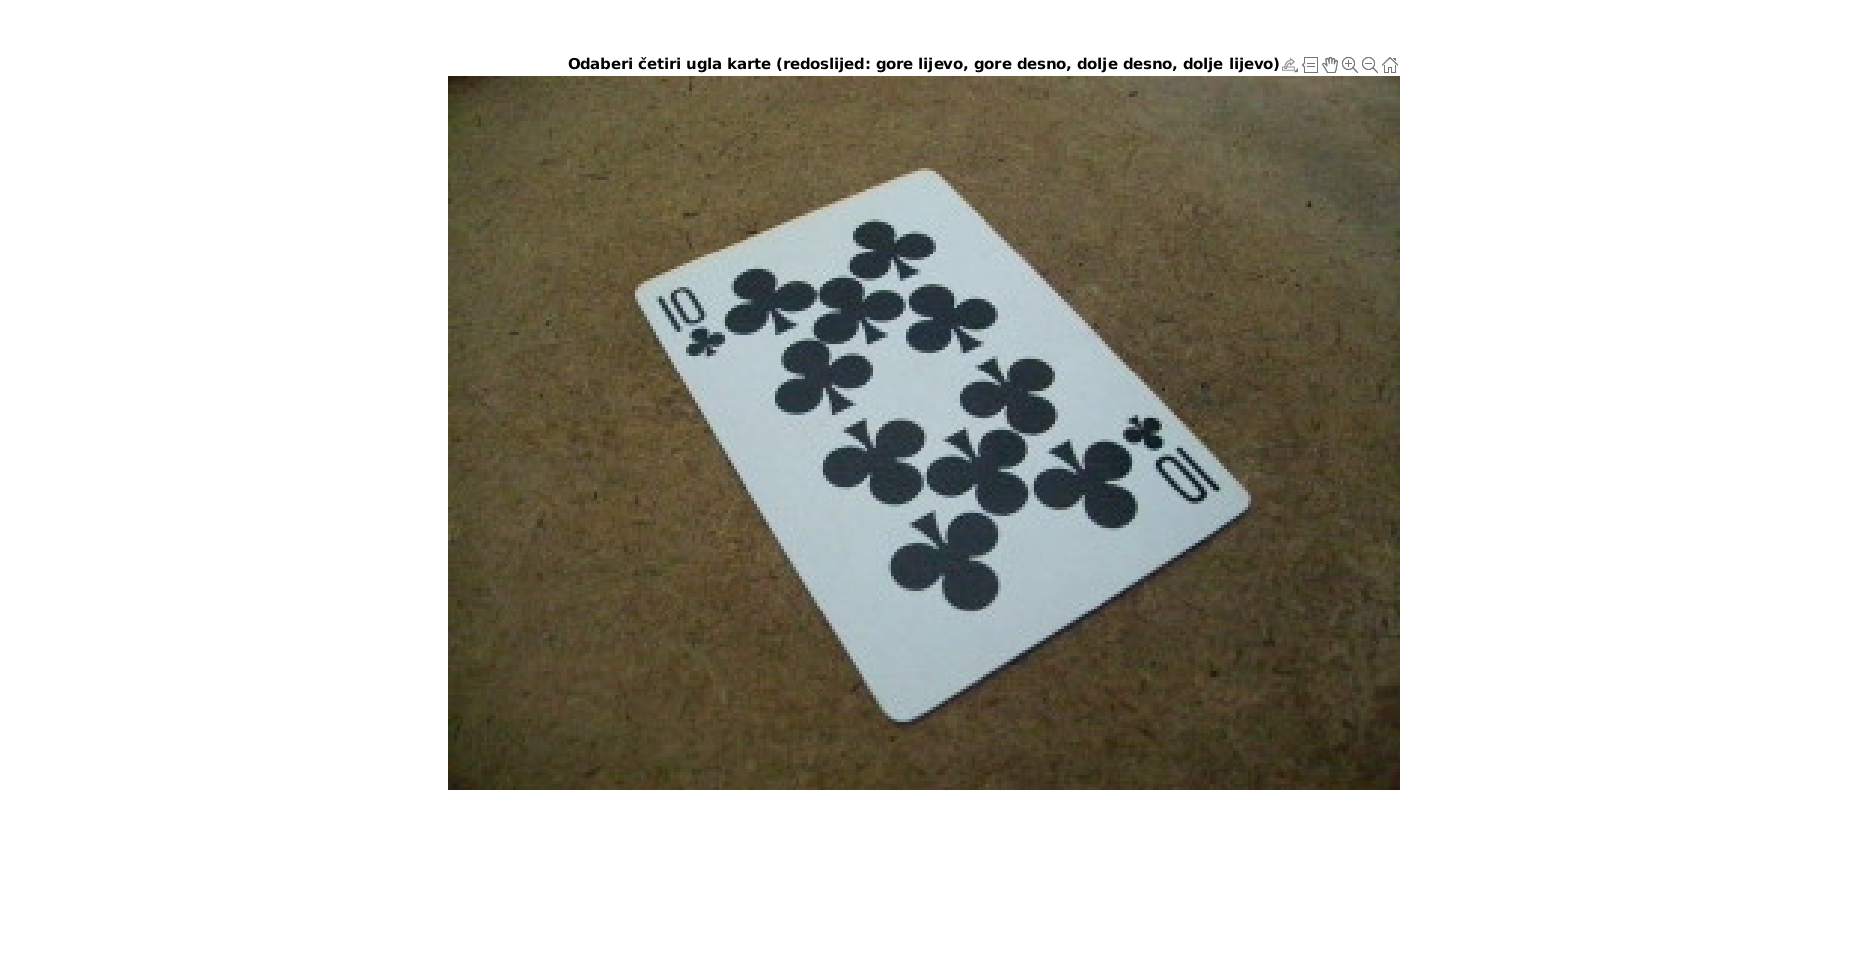

clc
clear all;
close all;


% Učitavanje slike
image = imread('card.jpg');

% Prikaz slike
imshow(image);
title('Odaberi četiri ugla karte (redoslijed: gore lijevo, gore desno, dolje desno, dolje lijevo)');
hold on;

% Odabir četiri točke koristeći impixel
[x, y] = ginput(4);

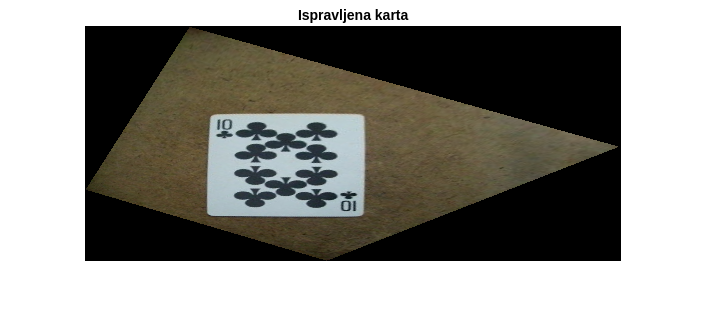


% Definirajte ciljane točke karte bez perspektivnih distorzija
targetPoints = [0, 0; 150, 0; 150, 100; 0, 100]; % Promijenite koordinate prema svojim odabranim točkama

% Procijenite perspektivnu transformaciju
tform = fitgeotrans([x, y], targetPoints, 'projective');

% Primijenite perspektivnu transformaciju na sliku
outputImage = imwarp(image, tform);

% Prikaz ispravljene karte
figure;
imshow(outputImage);
title('Ispravljena karta');